# UMAP projections testing for various number of dimensions

In the 8th notebook we are using only 3 dimensions for the UMAP projections and the parsing of the acoustic space in clusters. Let's explore more dimensions and see how the silouhette profiles are changing

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'), 'CallType', 'BatID','MPS_mic', 'MPS_mic_wf', 'MPS_mic_wt')
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'MicAudioGood');
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);

First restrict the MPS spectral frequency to 3 cycles/kHz and normalized all MPS

addpath(genpath('/Users/elie/Documents/CODE/GitHub/umapDistribution'))
IndWf = (MPS_mic_wf*1000)<=3; % Max Spectral frequency taken into account in cycles/kHz
NVoc = sum(MicAudioGood01);
MPS_mic_norm = cell(1,NVoc);
MPS_mic_focus = cell(1,NVoc);
MPS_mic_mean = reshape(mean(MPS_mic(MicAudioGood01,:), 'omitnan')',length(MPS_mic_wf), length(MPS_mic_wt));
IndMicAudioGood = find(MicAudioGood01);
for nn=1:NVoc
    vv=IndMicAudioGood(nn);
    MPS_local = reshape(MPS_mic(vv,:)',length(MPS_mic_wf), length(MPS_mic_wt));
    MPS_local = MPS_local(IndWf,:);
    MPS_mic_norm{nn} = reshape(MPS_local./MPS_mic_mean(IndWf,:), numel(MPS_local),1);
    MPS_mic_focus{nn} = reshape(MPS_local, numel(MPS_local),1);
end
MPS_mic_norm = [MPS_mic_norm{:}]';
MPS_mic_focus = [MPS_mic_focus{:}]';

Project all the data

You want to run these lines in the command window as the code open multiple figures and that messes up with the livescripts

Dim=[2 3 10 50 100];
[MPSmicReduction4Clustering,UMAP]= run_umap(MPS_mic_norm, 'metric','euclidean','n_component',Dim(1),'target_weight',0.55,'n_neighbors',10, 'min_dist',0.051);

Using MPS of all bats calculate an agglomerative hierarchical cluster tree Z

Z = linkage( MPSmicReduction4Clustering,'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)
title(sprintf('Tree with %d dimensions for UMAP', Dim(1)))

% Evaluate cluster quality accross various tree cut levels
ClustSize = 2:20;
MeanSilhouette = nan(length(Dim),length(ClustSize));
MedianSilhouette = nan(length(Dim),length(ClustSize));
PercLowSilhouette = nan(length(Dim),length(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4Clustering,T, 'Euclidean');
    MeanSilhouette(1,cc) = mean(Si);
    MedianSilhouette(1,cc) = median(Si);
    PercLowSilhouette(1,cc) = sum(Si<LowSi)/length(Si);
end

eva = evalclusters(MPSmicReduction4Clustering, 'linkage','CalinskiHarabasz','KList',1:15) %3 clusters

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 5.6671e+04 6.5031e+04 5.7135e+04 5.5327e+04 5.7018e+04 5.6951e+04 5.5229e+04 5.3280e+04 5.1392e+04 5.0424e+04 5.0274e+04 5.0926e+04 5.1757e+04 5.1799e+04]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','DaviesBouldin','KList',1:15) % 2 clusters

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.5731 0.6710 0.6281 0.8174 0.8918 0.9046 0.8312 0.8171 0.8765 0.9077 0.9286 0.9308 0.8938 0.9045]
           OptimalK: 2


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','silhouette','KList',1:15) % 2 clusters

eva =   SilhouetteEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.7951 0.7502 0.7386 0.6210 0.5754 0.5700 0.5679 0.5629 0.5408 0.5287 0.4988 0.5017 0.5105 0.5137]
           OptimalK: 2


Project all the data

You want to run these lines in the command window as the code open multiple figures and that messes up with the livescripts

[MPSmicReduction4Clustering,UMAP]= run_umap(MPS_mic_norm, 'metric','euclidean','n_component',Dim(2),'target_weight',0.55,'n_neighbors',10, 'min_dist',0.051);

Using MPS of all bats calculate an agglomerative hierarchical cluster tree Z

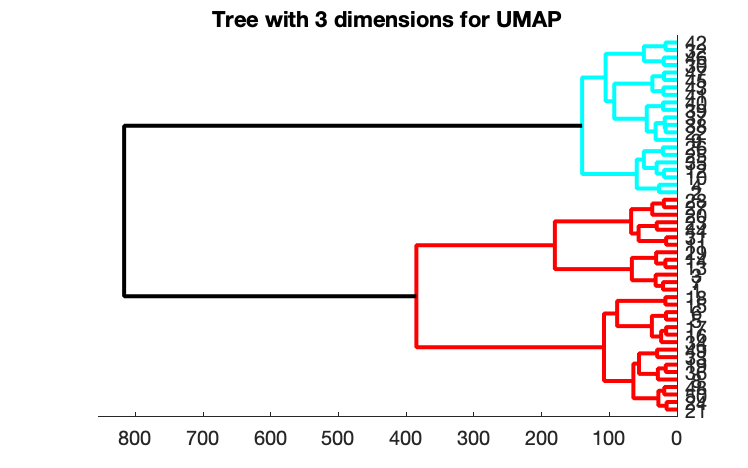

Z = linkage( MPSmicReduction4Clustering,'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)
title(sprintf('Tree with %d dimensions for UMAP', Dim(2)))

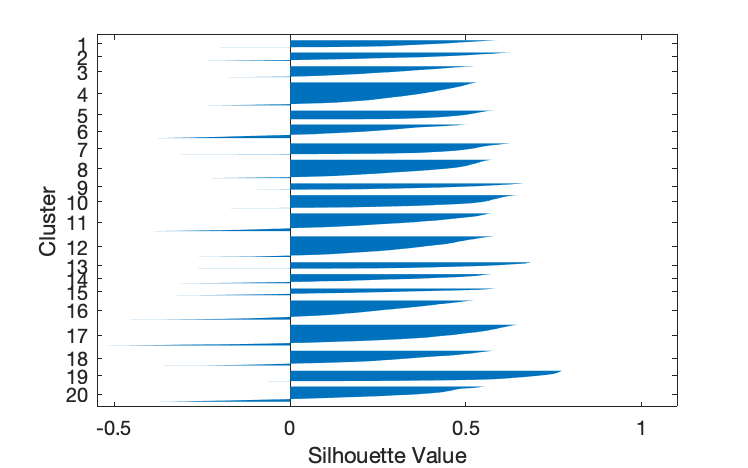

% Evaluate cluster quality accross various tree cut levels
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4Clustering,T, 'Euclidean');
    MeanSilhouette(2,cc) = mean(Si);
    MedianSilhouette(2,cc) = median(Si);
    PercLowSilhouette(2,cc) = sum(Si<LowSi)/length(Si);
end

eva = evalclusters(MPSmicReduction4Clustering, 'linkage','CalinskiHarabasz','KList',1:15) %3 clusters

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 6.2183e+04 7.4819e+04 6.5876e+04 6.0410e+04 5.5357e+04 5.3350e+04 5.1868e+04 5.1593e+04 4.9799e+04 4.8829e+04 4.8407e+04 4.8054e+04 4.7943e+04 4.8313e+04]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','DaviesBouldin','KList',1:15) % 2 clusters

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.5594 0.6481 0.6585 0.9542 1.1439 1.0924 0.9923 0.8951 0.9602 0.9765 1.0167 1.0166 0.9546 0.9071]
           OptimalK: 2


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','silhouette','KList',1:15) % 2 clusters

eva =   SilhouetteEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.8125 0.7705 0.7510 0.6012 0.4852 0.4937 0.5261 0.5365 0.5123 0.5089 0.5041 0.5047 0.5119 0.5331]
           OptimalK: 2


Project all the data

You want to run these lines in the command window as the code open multiple figures and that messes up with the livescripts

[MPSmicReduction4Clustering,UMAP]= run_umap(MPS_mic_norm, 'metric','euclidean','n_component',Dim(3),'target_weight',0.55,'n_neighbors',10, 'min_dist',0.051);

Using MPS of all bats calculate an agglomerative hierarchical cluster tree Z

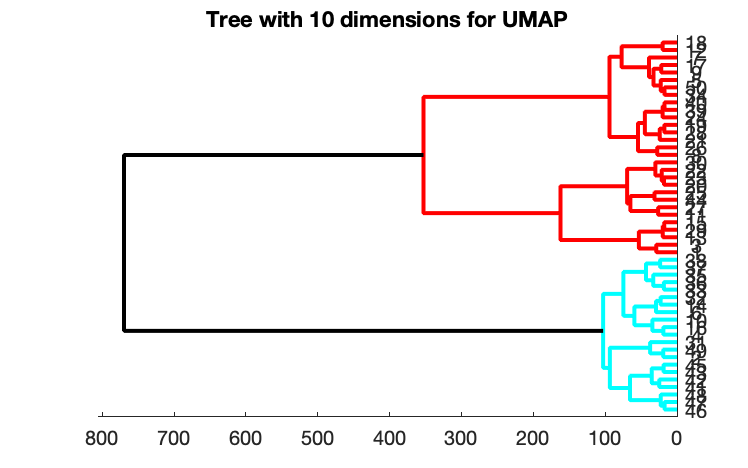

Z = linkage( MPSmicReduction4Clustering,'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)
title(sprintf('Tree with %d dimensions for UMAP', Dim(3)))

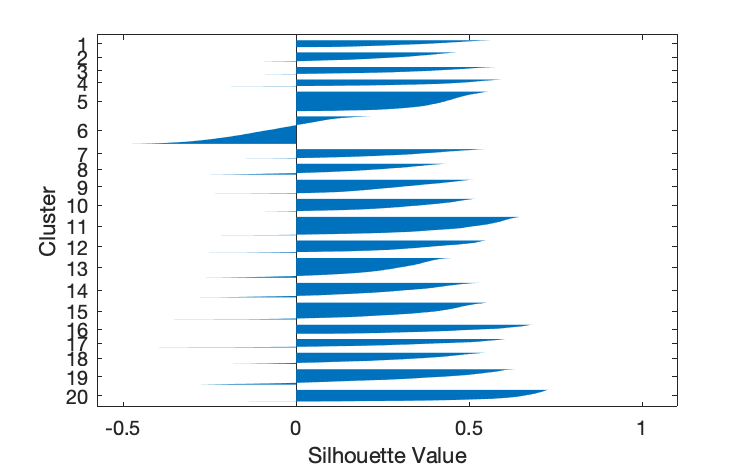

% Evaluate cluster quality accross various tree cut levels
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4Clustering,T, 'Euclidean');
    MeanSilhouette(3,cc) = mean(Si);
    MedianSilhouette(3,cc) = median(Si);
    PercLowSilhouette(3,cc) = sum(Si<LowSi)/length(Si);
end

eva = evalclusters(MPSmicReduction4Clustering, 'linkage','CalinskiHarabasz','KList',1:15) %3 clusters

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 6.5569e+04 7.7878e+04 6.7581e+04 5.7282e+04 5.1261e+04 4.8255e+04 4.5275e+04 4.3400e+04 4.2011e+04 4.1015e+04 4.0633e+04 4.0241e+04 3.9796e+04 3.9637e+04]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','DaviesBouldin','KList',1:15) % 2 clusters

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.5493 0.6567 0.6785 1.2125 1.4233 1.2704 1.1648 1.1671 1.2095 1.1766 1.0782 1.0286 1.0519 1.0637]
           OptimalK: 2


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','silhouette','KList',1:15) % 2 clusters

eva =   SilhouetteEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.8277 0.7808 0.7547 0.5634 0.4270 0.4501 0.4721 0.4711 0.4511 0.4605 0.4775 0.4852 0.4785 0.4653]
           OptimalK: 2


Project all the data

You want to run these lines in the command window as the code open multiple figures and that messes up with the livescripts

[MPSmicReduction4Clustering,UMAP]= run_umap(MPS_mic_norm, 'metric','euclidean','n_component',Dim(4),'target_weight',0.55,'n_neighbors',10, 'min_dist',0.051);

Using MPS of all bats calculate an agglomerative hierarchical cluster tree Z

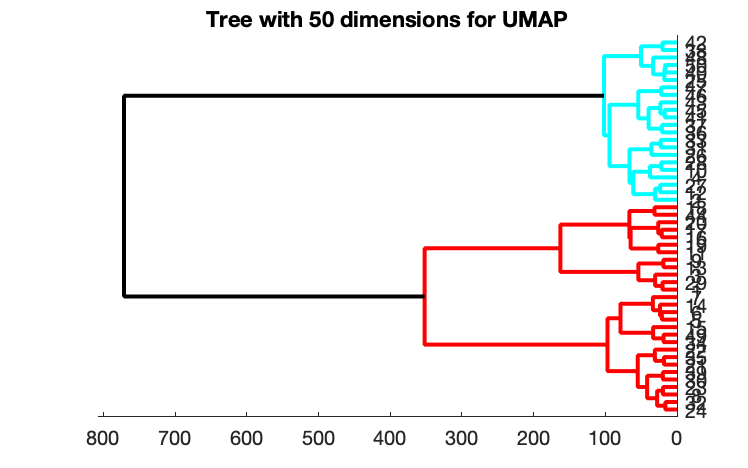

Z = linkage( MPSmicReduction4Clustering,'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)
title(sprintf('Tree with %d dimensions for UMAP', Dim(4)))

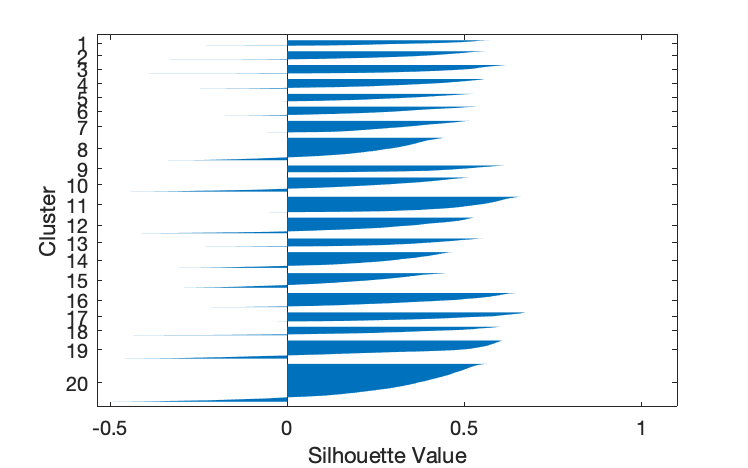

% Evaluate cluster quality accross various tree cut levels
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4Clustering,T, 'Euclidean');
    MeanSilhouette(4,cc) = mean(Si);
    MedianSilhouette(4,cc) = median(Si);
    PercLowSilhouette(4,cc) = sum(Si<LowSi)/length(Si);
end

eva = evalclusters(MPSmicReduction4Clustering, 'linkage','CalinskiHarabasz','KList',1:15) %3 clusters

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 6.6268e+04 7.8752e+04 6.8607e+04 5.8079e+04 5.2427e+04 4.9564e+04 4.6807e+04 4.4103e+04 4.2399e+04 4.1343e+04 4.0558e+04 3.9695e+04 3.9199e+04 3.9099e+04]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','DaviesBouldin','KList',1:15) % 2 clusters

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.5455 0.6559 0.6748 1.0406 1.2636 1.2779 1.1721 1.1926 1.1816 1.0931 1.0454 1.0691 1.0647 1.0766]
           OptimalK: 2


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','silhouette','KList',1:15) % 2 clusters

eva =   SilhouetteEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.8293 0.7828 0.7614 0.5763 0.4443 0.4633 0.4822 0.4710 0.4633 0.4688 0.4763 0.4728 0.4688 0.4565]
           OptimalK: 2


Project all the data

You want to run these lines in the command window as the code open multiple figures and that messes up with the livescripts

[MPSmicReduction4Clustering,UMAP]= run_umap(MPS_mic_norm, 'metric','euclidean','n_component',Dim(5),'target_weight',0.55,'n_neighbors',10, 'min_dist',0.051);

Using MPS of all bats calculate an agglomerative hierarchical cluster tree Z

Z = linkage( MPSmicReduction4Clustering,'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)
title(sprintf('Tree with %d dimensions for UMAP', Dim(5)))

% Evaluate cluster quality accross various tree cut levels
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4Clustering,T, 'Euclidean');
    MeanSilhouette(5,cc) = mean(Si);
    MedianSilhouette(5,cc) = median(Si);
    PercLowSilhouette(5,cc) = sum(Si<LowSi)/length(Si);
end

eva = evalclusters(MPSmicReduction4Clustering, 'linkage','CalinskiHarabasz','KList',1:15) %3 clusters

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 6.5880e+04 7.6180e+04 6.7849e+04 5.7489e+04 5.1417e+04 4.7943e+04 4.4945e+04 4.2843e+04 4.1239e+04 4.0328e+04 3.9284e+04 3.8620e+04 3.8357e+04 3.8156e+04]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','DaviesBouldin','KList',1:15) % 2 clusters

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.5469 0.6728 0.6942 1.0797 1.3013 1.3430 1.2257 1.1662 1.1598 1.1743 1.0985 1.0726 1.0663 1.0710]
           OptimalK: 2


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','silhouette','KList',1:15) % 2 clusters

eva =   SilhouetteEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.8288 0.7672 0.7579 0.5720 0.4323 0.4424 0.4606 0.4690 0.4542 0.4545 0.4591 0.4591 0.4514 0.4486]
           OptimalK: 2


figure()
plot(2:20,MeanSilhouette)
title('Mean Silhouette')
ylabel('Mean  Silhouette')
xlabel('# clusters')
legend('2 dim','3 dim', '10 dim', '50 dim', '100 dim')

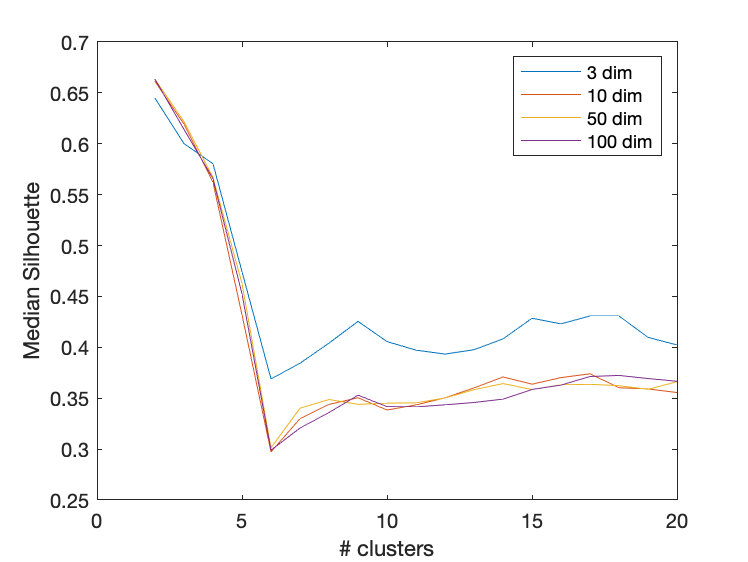


figure()
plot(2:20,MedianSilhouette)
ylabel('Median Silhouette')
xlabel('# clusters')
legend('2 dim','3 dim', '10 dim', '50 dim', '100 dim')

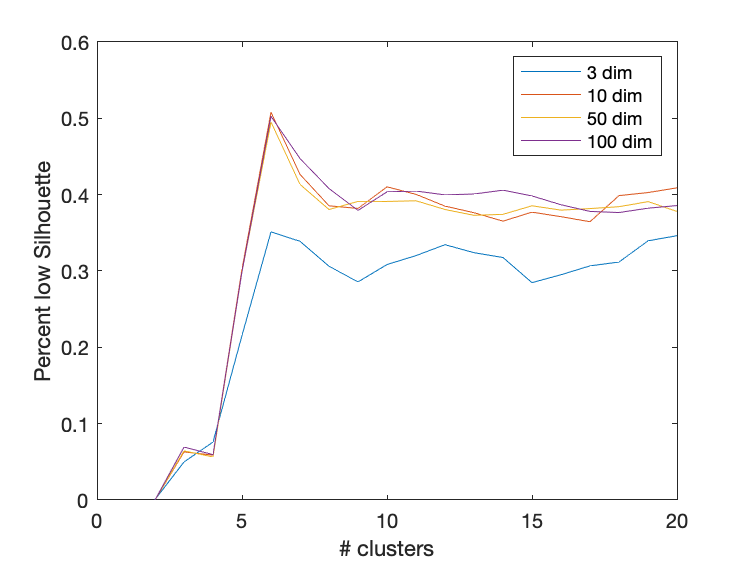


figure()
plot(2:20,PercLowSilhouette)
ylabel('Percent low Silhouette')
xlabel('# clusters')
legend('2 dim','3 dim', '10 dim', '50 dim', '100 dim')

The number of clusters that maximizes the mean and median silhouette and minimize the proportion of data points with low silhouette values is clearly 2. Now if we want to parse the acoustic space into reasonnable groups (with still reasonnable silhouette values) 4 seems ideal. There is no clear of the increase in the number of dimensions of UMAP. 3dim is doing as well as more dimensions, if not better for higher number of clusters

Load MPS from piezo to use both MPS into the clustering algo

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'), 'MPS', 'MPS_wf', 'MPS_wt')

Use both MPS (microphone + Piezo) to perform clustering of vocalizations

addpath(genpath('/Users/elie/Documents/CODE/GitHub/umapDistribution'))
IndWf = (MPS_wf*1000)<=3; % Max Spectral frequency taken into account in cycles/kHz
MPS_norm = cell(1,NVoc);
MPS_focus = cell(1,NVoc);
MPS_mean = reshape(mean(MPS(MicAudioGood01,:), 'omitnan')',length(MPS_wf), length(MPS_wt));
for nn=1:NVoc
    vv=IndMicAudioGood(nn);
    MPS_local = reshape(MPS(vv,:)',length(MPS_wf), length(MPS_wt));
    MPS_local = MPS_local(IndWf,:);
    MPS_norm{vv} = reshape(MPS_local./MPS_mean(IndWf,:), numel(MPS_local),1);
    MPS_focus{vv} = reshape(MPS_local, numel(MPS_local),1);
end
MPS_norm = [MPS_norm{:}]';
MPS_focus = [MPS_focus{:}]';

Create the new variable

MPS_mic_piezo_norm = [MPS_mic_norm MPS_norm];

Run a UMAP with the new concatenated vector of MPSs

You want to run these lines in the command window as the code open multiple figures and that messes up with the livescripts

[MPSmicReduction4Clustering,UMAP]= run_umap(MPS_mic_piezo_norm, 'metric','euclidean','n_component',Dim(1),'target_weight',0.55,'n_neighbors',10, 'min_dist',0.051);

Run a UMAP with the new concatenated vector of MPSs

You want to run these lines in the command window as the code open multiple figures and that messes up with the livescripts

[MPSmicReduction4Clustering,UMAP]= run_umap(MPS_mic_piezo_norm, 'metric','euclidean','n_component',Dim(2),'target_weight',0.55,'n_neighbors',10, 'min_dist',0.051);

Using MPS of all bats calculate an agglomerative hierarchical cluster tree Z

Z = linkage( MPSmicReduction4Clustering,'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)
title(sprintf('Tree with %d dimensions for UMAP with 2 MPS', Dim(2)))

% Evaluate cluster quality accross various tree cut levels
ClustSize = 2:20;
MeanSilhouette2MPS = nan(length(Dim),length(ClustSize));
MedianSilhouette2MPS = nan(length(Dim),length(ClustSize));
PercLowSilhouette2MPS = nan(length(Dim),length(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4Clustering,T, 'Euclidean');
    MeanSilhouette2MPS(1,cc) = mean(Si);
    MedianSilhouette2MPS(1,cc) = median(Si);
    PercLowSilhouette2MPS(1,cc) = sum(Si<LowSi)/length(Si);
end

eva = evalclusters(MPSmicReduction4Clustering, 'linkage','CalinskiHarabasz','KList',1:15) %3 clusters

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 4.7224e+04 6.1389e+04 5.8210e+04 5.3772e+04 5.0596e+04 4.8546e+04 4.7625e+04 4.4968e+04 4.3189e+04 4.2220e+04 4.1843e+04 4.2078e+04 4.2404e+04 4.1682e+04]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','DaviesBouldin','KList',1:15) % 2 clusters

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.6495 0.6601 0.6835 0.9428 0.9130 0.9881 1.0097 1.0236 0.9579 1.0181 1.0293 1.0200 1.0197 0.9824]
           OptimalK: 2


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','silhouette','KList',1:15) % 2 clusters

eva =   SilhouetteEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.7266 0.7192 0.7284 0.5892 0.6034 0.4892 0.4905 0.4533 0.4606 0.4710 0.4570 0.4635 0.4740 0.4791]
           OptimalK: 4


Run a UMAP with the new concatenated vector of MPSs

You want to run these lines in the command window as the code open multiple figures and that messes up with the livescripts

[MPSmicReduction4Clustering,UMAP]= run_umap(MPS_mic_piezo_norm, 'metric','euclidean','n_component',Dim(3),'target_weight',0.55,'n_neighbors',10, 'min_dist',0.051);

Using MPS of all bats calculate an agglomerative hierarchical cluster tree Z

Z = linkage( MPSmicReduction4Clustering,'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)
title(sprintf('Tree with %d dimensions for UMAP with 2 MPS', Dim(3)))

% Evaluate cluster quality accross various tree cut levels
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4Clustering,T, 'Euclidean');
    MeanSilhouette2MPS(2,cc) = mean(Si);
    MedianSilhouette2MPS(2,cc) = median(Si);
    PercLowSilhouette2MPS(2,cc) = sum(Si<LowSi)/length(Si);
end

eva = evalclusters(MPSmicReduction4Clustering, 'linkage','CalinskiHarabasz','KList',1:15) %3 clusters

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 4.8204e+04 5.7037e+04 5.2207e+04 5.0744e+04 4.5839e+04 4.1818e+04 3.9176e+04 3.7490e+04 3.6050e+04 3.5231e+04 3.4884e+04 3.4496e+04 3.3879e+04 3.3576e+04]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','DaviesBouldin','KList',1:15) % 2 clusters

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.6611 0.6844 0.7169 0.8304 1.0423 1.2129 1.3026 1.3083 1.2448 1.1579 1.1863 1.1149 1.1124 1.0930]
           OptimalK: 2


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','silhouette','KList',1:15) % 2 clusters

eva =   SilhouetteEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.7363 0.6911 0.6987 0.5729 0.5137 0.4332 0.4461 0.4181 0.4130 0.4067 0.3922 0.4075 0.4157 0.4233]
           OptimalK: 2


Run a UMAP with the new concatenated vector of MPSs

You want to run these lines in the command window as the code open multiple figures and that messes up with the livescripts

[MPSmicReduction4Clustering,UMAP]= run_umap(MPS_mic_piezo_norm, 'metric','euclidean','n_component',Dim(4),'target_weight',0.55,'n_neighbors',10, 'min_dist',0.051);

Using MPS of all bats calculate an agglomerative hierarchical cluster tree Z

Z = linkage( MPSmicReduction4Clustering,'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)
title(sprintf('Tree with %d dimensions for UMAP with 2 MPS', Dim(4)))

% Evaluate cluster quality accross various tree cut levels
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4Clustering,T, 'Euclidean');
    MeanSilhouette2MPS(3,cc) = mean(Si);
    MedianSilhouette2MPS(3,cc) = median(Si);
    PercLowSilhouette2MPS(3,cc) = sum(Si<LowSi)/length(Si);
end

eva = evalclusters(MPSmicReduction4Clustering, 'linkage','CalinskiHarabasz','KList',1:15) %3 clusters

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 4.7599e+04 6.0597e+04 5.8537e+04 5.2198e+04 4.7173e+04 4.3666e+04 4.1758e+04 3.9491e+04 3.7909e+04 3.6819e+04 3.6281e+04 3.6073e+04 3.6331e+04 3.6069e+04]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','DaviesBouldin','KList',1:15) % 2 clusters

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.6451 0.6841 0.7070 1.0092 1.1128 1.2340 1.2263 1.1590 1.1935 1.1947 1.1729 1.1530 1.1011 1.0895]
           OptimalK: 2


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','silhouette','KList',1:15) % 2 clusters

eva =   SilhouetteEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.7352 0.7176 0.7312 0.5724 0.4584 0.4452 0.4380 0.4460 0.4298 0.4299 0.4347 0.4463 0.4613 0.4786]
           OptimalK: 2


Run a UMAP with the new concatenated vector of MPSs

You want to run these lines in the command window as the code open multiple figures and that messes up with the livescripts

[MPSmicReduction4Clustering,UMAP]= run_umap(MPS_mic_piezo_norm, 'metric','euclidean','n_component',Dim(5),'target_weight',0.55,'n_neighbors',10, 'min_dist',0.051);

n\_neighbors=\color{blue}10\color{black}, min\_dist=\color{blue}0.051\color{black}, metric=\color{blue}euclidean\color{black},randomize=\color{blue}0\color{black}, labels=\color{blue}0


UMAP(method=Java, n_neighbors=10, n_components=100, metric=euclidean, n_epochs=[], learning_rate=1, init=spectral, min_dist=0.051, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=1.74663698054226, b=0.843107979259552, random_state=true, metric_kwds=[], target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.55, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]


Using MPS of all bats calculate an agglomerative hierarchical cluster tree Z

Z = linkage( MPSmicReduction4Clustering,'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)
title(sprintf('Tree with %d dimensions for UMAP with 2 MPS', Dim(5)))

% Evaluate cluster quality accross various tree cut levels
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4Clustering,T, 'Euclidean');
    MeanSilhouette2MPS(4,cc) = mean(Si);
    MedianSilhouette2MPS(4,cc) = median(Si);
    PercLowSilhouette2MPS(4,cc) = sum(Si<LowSi)/length(Si);
end

eva = evalclusters(MPSmicReduction4Clustering, 'linkage','CalinskiHarabasz','KList',1:15) %3 clusters

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 4.7242e+04 5.9423e+04 5.5346e+04 4.9460e+04 4.5699e+04 4.3039e+04 4.0582e+04 3.8366e+04 3.7026e+04 3.6001e+04 3.5521e+04 3.5147e+04 3.4532e+04 3.4145e+04]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','DaviesBouldin','KList',1:15) % 2 clusters

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.6473 0.6896 0.7117 1.0395 1.1040 1.1941 1.2621 1.2551 1.1912 1.1722 1.1587 1.1238 1.0811 1.0957]
           OptimalK: 2


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','silhouette','KList',1:15) % 2 clusters

eva =   SilhouetteEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.7342 0.7113 0.7109 0.5569 0.5147 0.4465 0.4232 0.4235 0.4338 0.4122 0.4227 0.4370 0.4351 0.4337]
           OptimalK: 2


figure()
plot(2:20,MeanSilhouette2MPS)
title('Mean Silhouette')
ylabel('Mean  Silhouette')
xlabel('# clusters')
legend('3 dim', '10 dim', '50 dim', '100 dim')

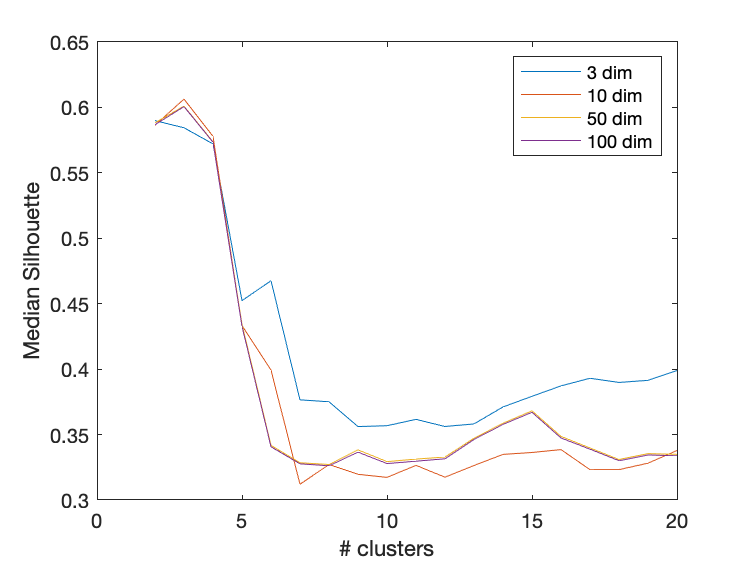


figure()
plot(2:20,MedianSilhouette2MPS)
ylabel('Median Silhouette')
xlabel('# clusters')
legend('3 dim', '10 dim', '50 dim', '100 dim')

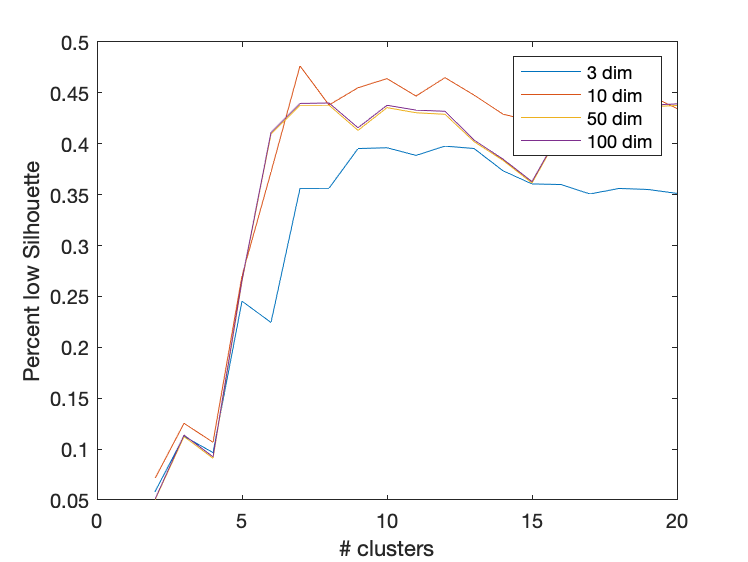


figure()
plot(2:20,PercLowSilhouette2MPS)
ylabel('Percent low Silhouette')
xlabel('# clusters')
legend('3 dim', '10 dim', '50 dim', '100 dim')

figure()
plot(2:20,MeanSilhouette)
hold on
plot(2:20,MeanSilhouette2MPS, '--')
title('Mean Silhouette')
ylabel('Mean  Silhouette')
xlabel('# clusters')
legend('3 dim 1MPS', '10 dim 1MPS', '50 dim 1MPS', '100 dim 1MPS','3 dim 2MPS', '10 dim 2MPS', '50 dim 2MPS', '100 dim 2MPS')
hold off

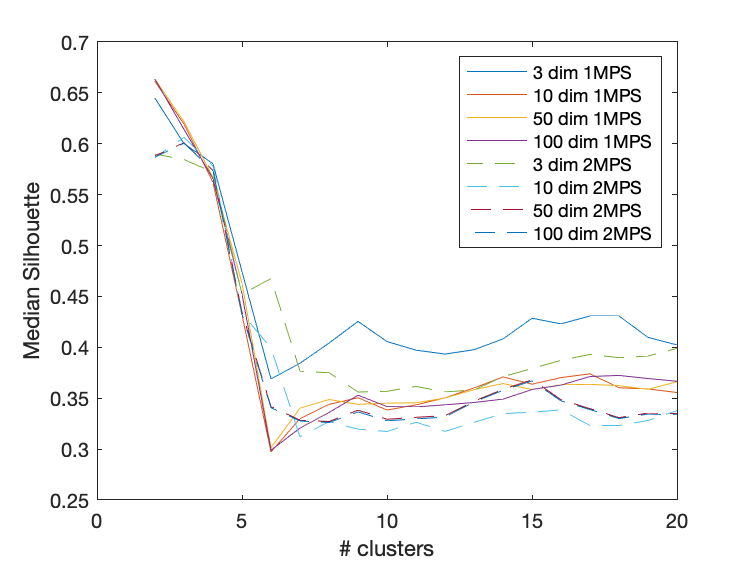


figure()
plot(2:20,MedianSilhouette)
hold on
plot(2:20,MedianSilhouette2MPS, '--')
ylabel('Median Silhouette')
xlabel('# clusters')
legend('2 dim 1MPS','3 dim 1MPS', '10 dim 1MPS', '50 dim 1MPS', '100 dim 1MPS','3 dim 2MPS', '10 dim 2MPS', '50 dim 2MPS', '100 dim 2MPS')
hold off

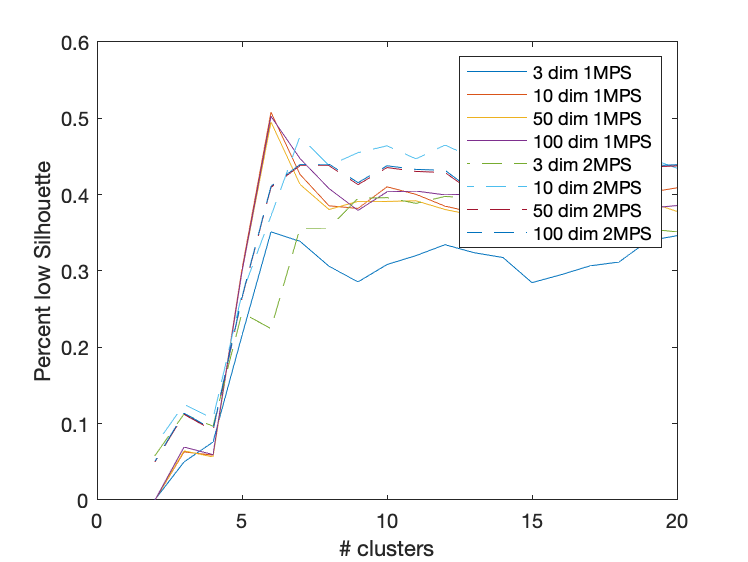


figure()
plot(2:20,PercLowSilhouette)
hold on
plot(2:20,PercLowSilhouette2MPS, '--')
ylabel('Percent low Silhouette')
xlabel('# clusters')
legend('2 dim 1MPS', '3 dim 1MPS', '10 dim 1MPS', '50 dim 1MPS', '100 dim 1MPS','3 dim 2MPS', '10 dim 2MPS', '50 dim 2MPS', '100 dim 2MPS')
hold off

With 2 MPS the optimal number of dimensions for the clusterability is 10. The optimal number of clusters would be 4. There is no clear benefit of using 2 MPS instead of 1 though.

rerun with 10 dimensions and save the output values

[MPSmicReduction4Clustering,UMAP]= run_umap(MPS_mic_piezo_norm, 'metric','euclidean','n_component',10,'target_weight',0.55,'n_neighbors',10, 'min_dist',0.051);

NGroups=4;
 Z = linkage( MPSmicReduction4Clustering,'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D, TmicpiezoAll7, ~] = dendrogram(Z,NGroups, 'ColorThreshold','Default','Orientation','left');
set(D,'LineWidth',2)
title('Tree with 10 dimensions for UMAP with 2 MPS 4groups')

save(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_UMAPMicPiezo.mat'), 'TmicpiezoAll4','MPSmicReduction4Clustering','MeanSilhouette2MPS', 'MedianSilhouette2MPS')
save(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls_UMAPMicPiezo.mat'), 'TmicpiezoAll4','MPSmicReduction4Clustering','MeanSilhouette2MPS', 'MedianSilhouette2MPS')

With the mic MPS the optimal number of dimensions for the clusterability is 3. The optimal number of clusters would be 4 (according to mean and median Silhouette)

rerun with 3 dimensions and save the output values

[MPSmicReduction4Clustering,UMAP]= run_umap(MPS_mic_norm, 'metric','euclidean','n_component',3,'target_weight',0.55,'n_neighbors',10, 'min_dist',0.051);

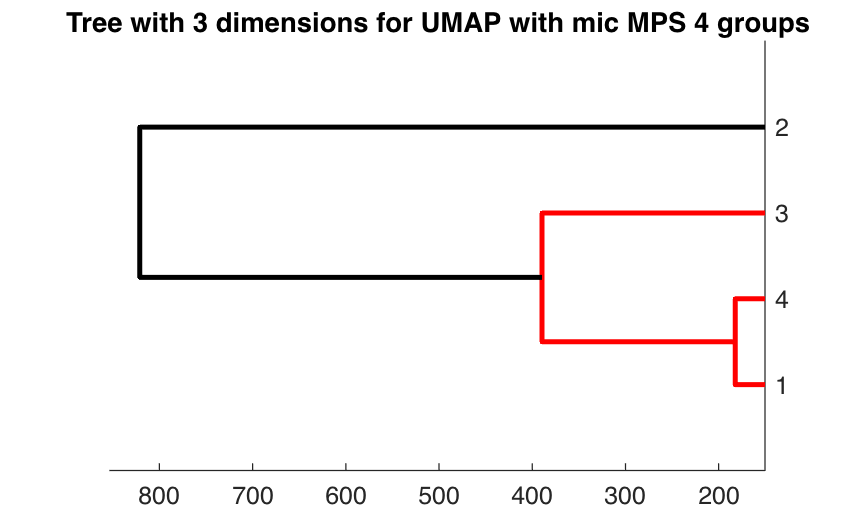

NGroups=4;
 Z = linkage( MPSmicReduction4Clustering,'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D, TmicAll4, ~] = dendrogram(Z,NGroups, 'ColorThreshold','Default','Orientation','left');
set(D,'LineWidth',2)
title('Tree with 3 dimensions for UMAP with mic MPS 4 groups')

save(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_UMAPMic.mat'), 'TmicAll4','MPSmicReduction4Clustering','MeanSilhouette', 'MedianSilhouette')
save(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls_UMAPMic.mat'), 'TmicAll4','MPSmicReduction4Clustering','MeanSilhouette', 'MedianSilhouette')

With the mic MPS the optimal number of dimensions for the clusterability is 2. The optimal number of clusters would be 4 (according to mean and median Silhouette)

rerun with 2 dimensions and save the output values

[MPSmicReduction4Clustering,UMAP]= run_umap(MPS_mic_norm, 'metric','euclidean','n_component',2,'target_weight',0.55,'n_neighbors',10, 'min_dist',0.051);

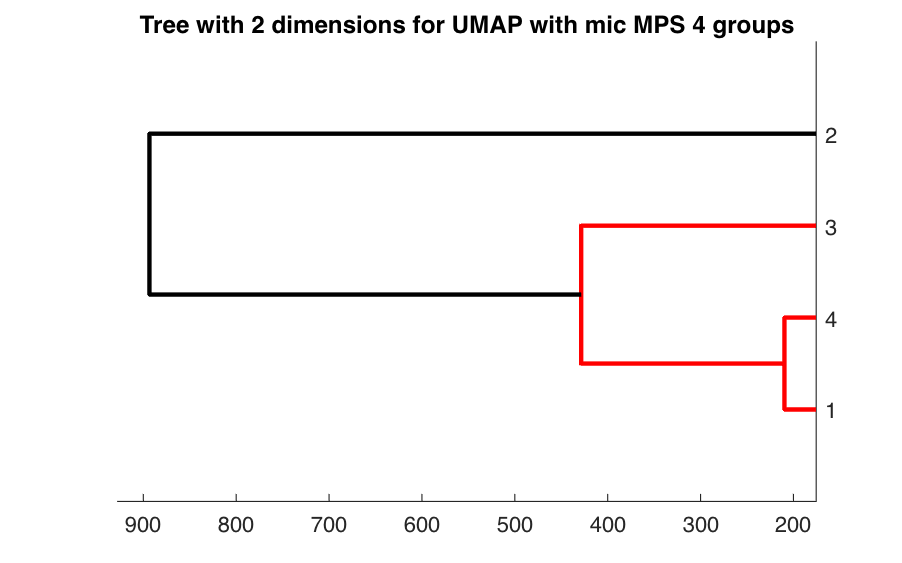

NGroups=4;
 Z = linkage( MPSmicReduction4Clustering,'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D, TmicAll4, ~] = dendrogram(Z,NGroups, 'ColorThreshold','Default','Orientation','left');
set(D,'LineWidth',2)
title('Tree with 2 dimensions for UMAP with mic MPS 4 groups')

save(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_2DUMAPMic.mat'), 'TmicAll4','MPSmicReduction4Clustering','MeanSilhouette', 'MedianSilhouette')
save(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls_2DUMAPMic.mat'), 'TmicAll4','MPSmicReduction4Clustering','MeanSilhouette', 'MedianSilhouette')